syms t ;
t0=0.15;
m(t)=piecewise(0<=t<t0./3,0.5,t0./3<=t<2.*t0./3,-1,0);
ConvAM=@(Ac,u,m,fc)(Ac*(1+u.*m).*cos(2*pi*fc*t))

ConvAM = function_handle with value:
    @(Ac,u,m,fc)(Ac*(1+u.*m).*cos(2*pi*fc*t))


xc=ConvAM(1,0.85,m,250)

$$xc(t) = \left\{ \begin{array}{cl} \frac{57\,\cos\left(500\,\pi \,t\right)}{40} & \text{ if }t\in \left[0,\frac{1}{20}\right)\\ \frac{3\,\cos\left(500\,\pi \,t\right)}{20} & \text{ if }t\in \left[\frac{1}{20},\frac{1}{10}\right)\\ \cos\left(500\,\pi \,t\right) & \mathrm{otherwise} \end{array}\right.$$

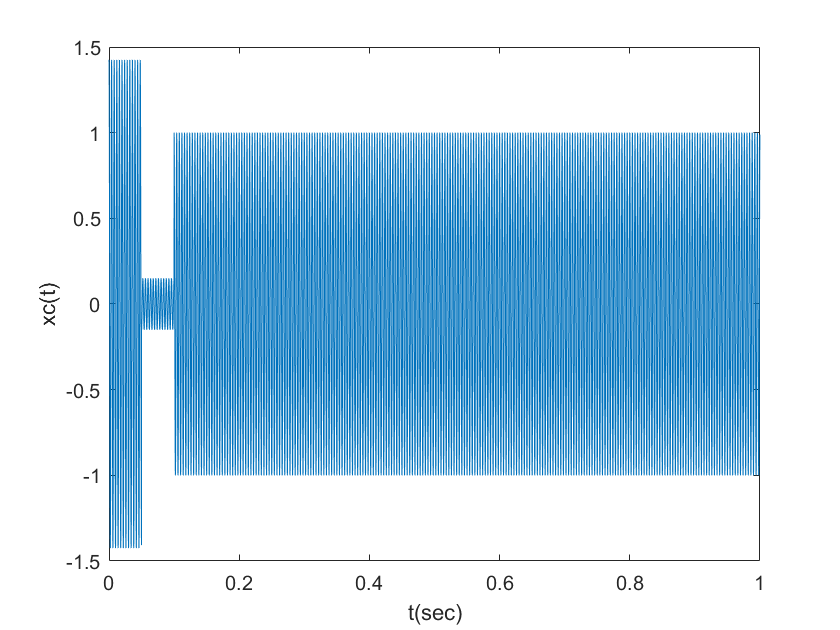

t=0:0.0001:1-0.0001;
XC=xc(t);
plot(t,double(XC))

xlabel("t(sec)")
ylabel("xc(t)")

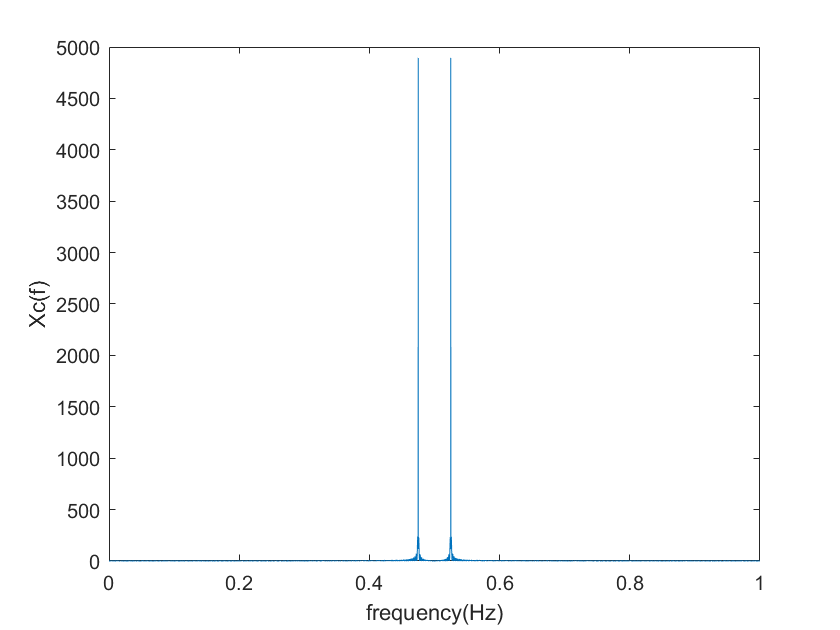

Y=fftshift(fft(double(XC)));
plot(t,abs(Y))
xlabel("frequency(Hz)")
ylabel("Xc(f)")

sx=(1/t0).*int(((abs(m)).^2),0,t0);
power=(1/2)+((1/2).*((0.85).^2).*sx)

$$power = \frac{1249}{1920}$$

powersb=power-0.5

$$powersb = \frac{289}{1920}$$

efficieny=double(((power-0.5)/power))

efficieny = 0.2314

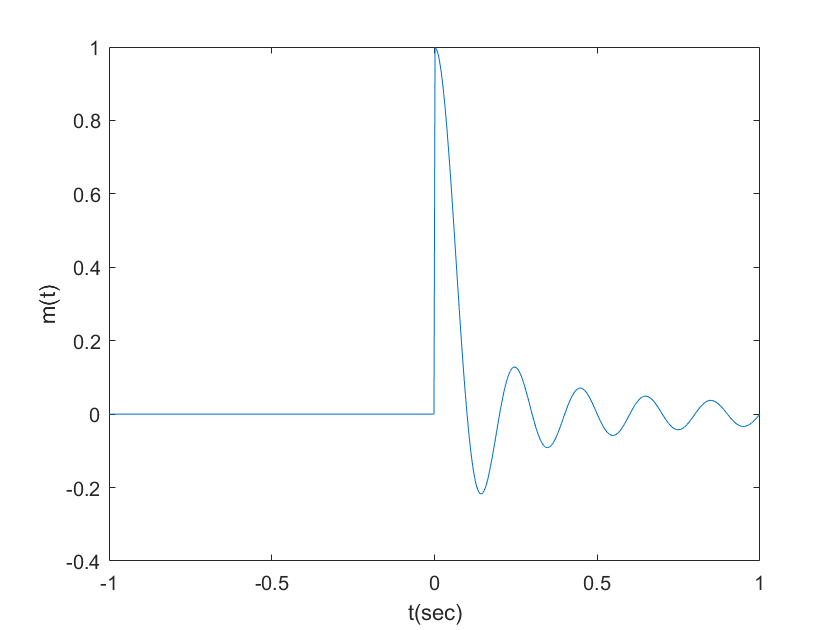

t=-1:1/600:1;
m2=sinc(10*t).*(heaviside(t)-heaviside(t-1))+heaviside(-t)*0;
plot(t,m2)
xlabel("t(sec)")
ylabel("m(t)")
M=fft(m2);

mf=fftshift(M);
f=fftshift(t);
plot(t,abs(mf))
xlabel("frequency(Hz)")
ylabel("M(f)")

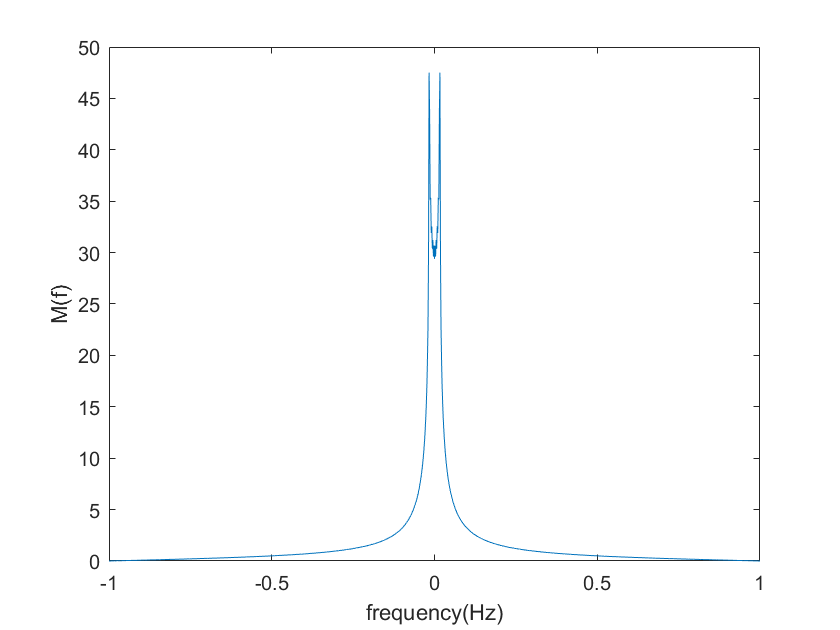

%part a and b of question 2 must be runned in script the file name 

%is u12.m and all graphs are presented there.

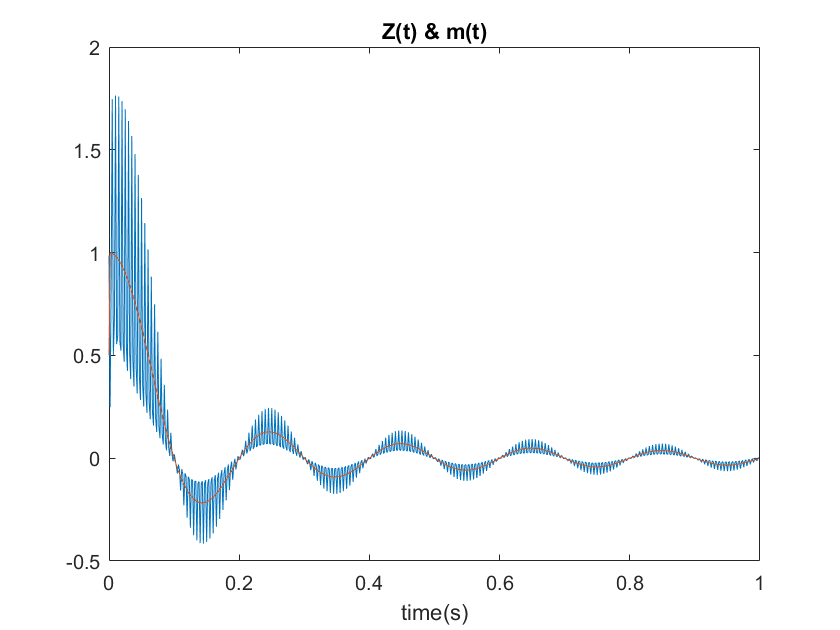

%  t=-1:1/600:1-1/600;
t=0:1/600:1-1/600;
    m2=sinc(10*t).*(heaviside(t)-heaviside(t-1))+heaviside(-t)*0;
    Ac=1;
    fc=100;
    fs=600;
    DSB=@(Ac,m2,fc)((Ac.*m2).*cos(2*pi*fc*t));
    xc2=DSB(Ac,m2,fc);
% Ac=1;
% fc=100;
% fs=600;
%     [xc2]=xis(m3,fc,Ac);

    [zt yt]=dem(xc2,fc,Ac,fs);
    figure
plot(t,zt,t,m2)                                
title('Z(t) & m(t)');                        
xlabel('time(s)');
plot(t,yt)
title('y(t)');                        
xlabel('time(s)');
plot(t,zt)

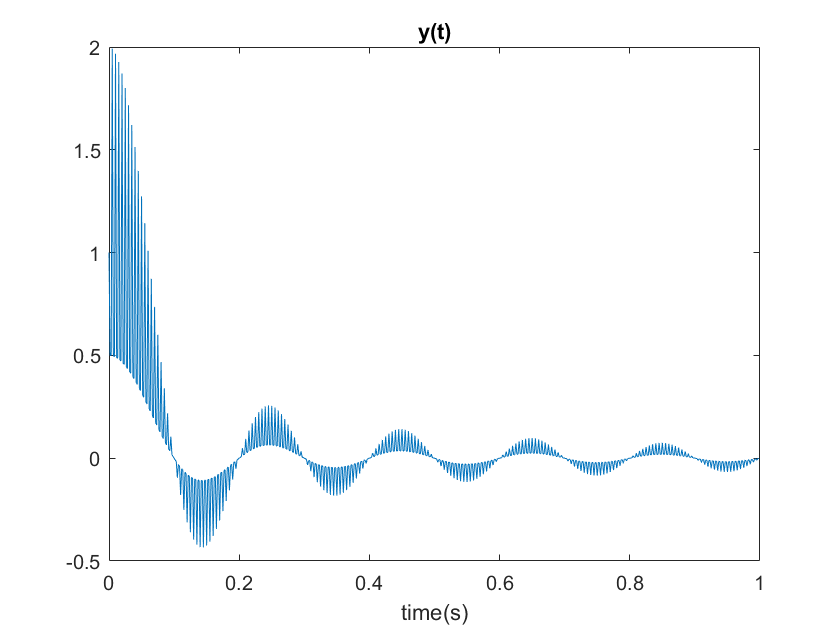

title('z(t)');                        
xlabel('time(s)');
ytf=fftshift(fft(yt));

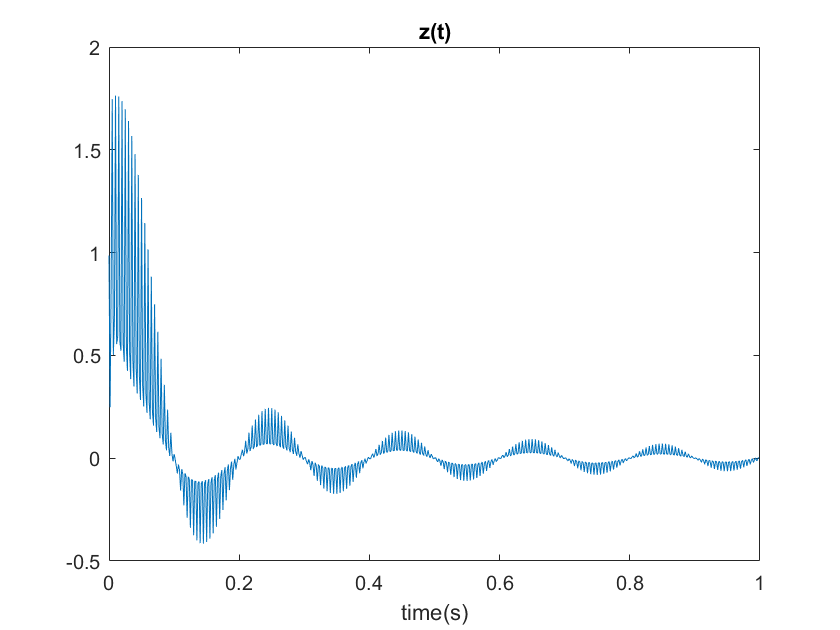

plot(t,abs(ytf)),title('Y(f)'),  xlabel('frequency(Hz)')  
ztf=fftshift(fft(zt));
plot(t,abs(ztf)),xlabel('time(s)'),title('Z(f)')

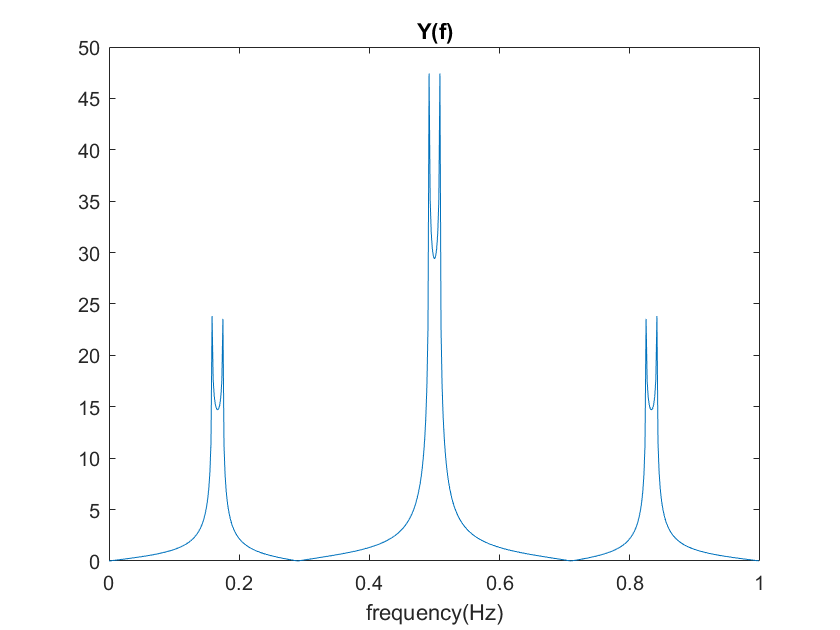


m2=sinc(10*t).*(heaviside(t)-heaviside(t-1))+heaviside(-t)*0;

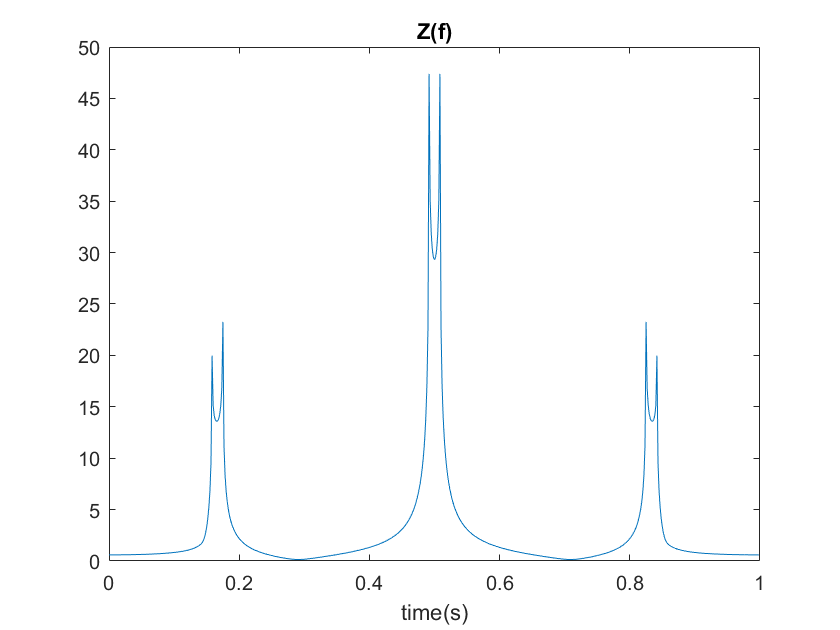

error=immse(m2,zt)


index=0;
t=0:1/600:1-1/600;

error = 0.0201

    m2=sinc(10*t).*(heaviside(t)-heaviside(t-1))+heaviside(-t)*0;
    Ac=1;
    fc=100;

Matrix dimensions must agree.

Error in CA2_MAHSAHEYDARI>@(Ac,m2,fc)((Ac.*m2).*cos(2*pi*fc*t))

error1 = 0.0984

fc =   -500  -490  -480  -470  -460  -450  -440  -430  -420  -410  -400  -390  -380  -370  -360  -350  -340  -330  -320  -310  -300  -290  -280  -270  -260  -250  -240  -230  -220  -210  -200  -190  -180  -170  -160  -150  -140  -130  -120  -110  -100   -90   -80   -70   -60   -50   -40   -30   -20   -10


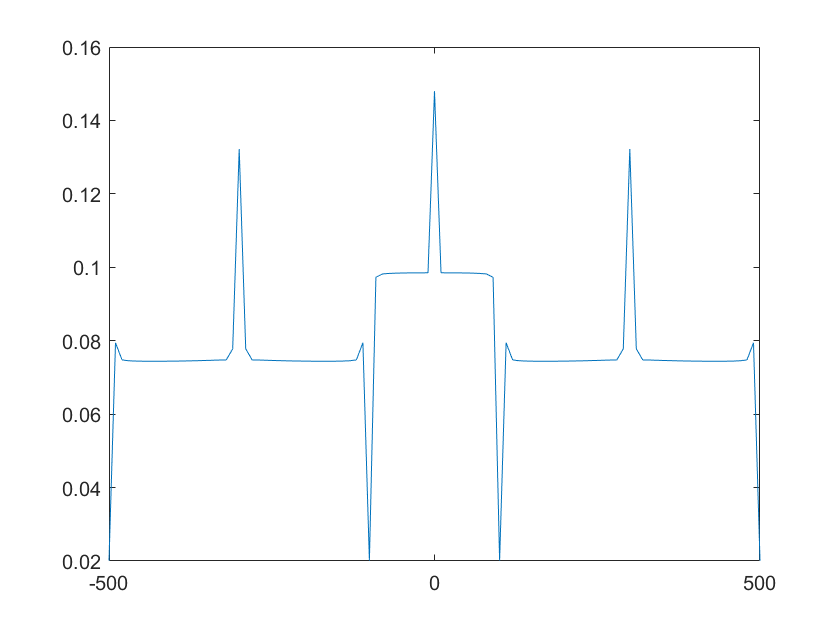

    fs=600;
    DSB=@(Ac,m2,fc)((Ac.*m2).*cos(2*pi*fc*t));
    xc2=DSB(Ac,m2,fc);
for fc=-500:10:500 
index=index+1;
xc=DSB(Ac,m2,fc);
[zt,yt]=dem(xc,fc,Ac);
data(index)=immse(zt,m2) ;  
end

fc=-500:10:500
plot(fc,data)